## Reto: modelacion de supercapacitores

Michelle Andrea Arceo Solano A01625268

Miguel Ángel Chávez Robles A01620402

Pedro Alan Gónzalez Arámbula A01625308

Matías Kochlowski A01625364

### Explicación de supercapacitores y circuitos equivalentes

**Supercapacitores** 

Los supercapacitores son dispositivos que almacenan energía de larga duración, tienen alta densidad de energía, alta intensidad de potencia y alta resistencia interna. La base de operación es la interfaz entre un conductor iónico (electrolito) y un conductor eléctrico (electrodo). Cuando hay una diferencia de potencia, los electrones se acumulan en el conductor eléctrico que se encuentra conectado a la terminal negativa y por ende atrae iones positivos del conductor iónico que a su vez atrae iones negativos para balancear la carga. En el otro conductor eléctrico se acumulan cargas positivas mientras atrae iones negativos del conductor iónico, entre tanto la corriente fluye a través de una carga externa. Esta distribución crea dos capacitores, puesto que los cationes y aniones están localizados junto a los conductores eléctricos, por lo que es llamado “doble capa”, al estar conectado por la resistencia del conductor iónico, esta resistencia es más baja que una resistencia interna de una batería por lo que los supercapacitores pueden conseguir densidades de potencia más altas que las baterías.  

Los supercapacitores tienen una composición de tres componentes fundamentales: dos electrodos, el electrolito y el separador. 

La ecuación de la energía almacenada en un supercapacitor es: 

Donde:  

C = Capacitancia (Faradios) 

V = Voltaje (Volts) 

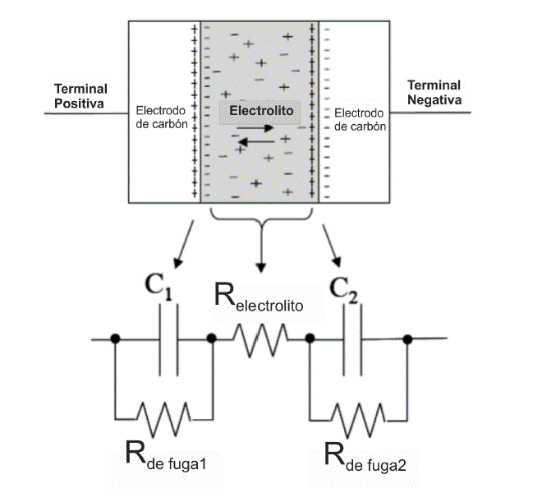Fig. 1 Circuito equivalente de un supercapacitor

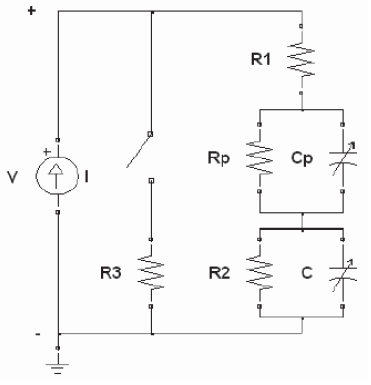Fig.2 Modelo conceptual de un supercapacitor

En esta la resistencia R2 está conectada en paralelo con un condensador que representa la cantidad de efecto de auto descarga. La resistencia R1 representa las pérdidas de cargas que se originan a la resistencia del elemento conductor y el proceso no es el ideal. La resistencia R3 proporciona la protección contra sobretensión, evita daños en los elementos del supercapacitor, por lo que al equilibrar el voltaje de las celdas se evita que el voltaje en solo una celda aumente y esto produzca una explosión. Esta diferencia de voltaje cuando una capacitancia es más pequeña o grande que la otra y se puede observar en la cantidad de energía almacenada. Las resistencias Rp y Cp se incluyen en el circuito para estructurar en los procesos más rápidos en el comportamiento del supercapacitor. A diferencia del circuito del documento, esta tiene más componentes pero es solo un modelo conceptual de un supercapacitor. 

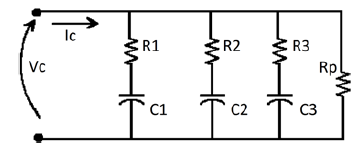Fig.3 Circuito equivalente de un supercapacitor

Este a diferencia del circuito equivalente que se presenta en el documento, es de tres ramas, por lo que se puede observar que tiene una resistencia y capacitancia más y Rp se encuentra al final del circuito mientras que el nuestro se encuentra al inicio, este modelo se basa de 3 constantes de tiempo, sin tomar en cuenta que la capacidad depende de la tensión sin embargo si considera que las cargas se encuentran desajustadas de los condensadores de cada rama. 

### Modelo de circuito equivalente de supercapacitor en carga.

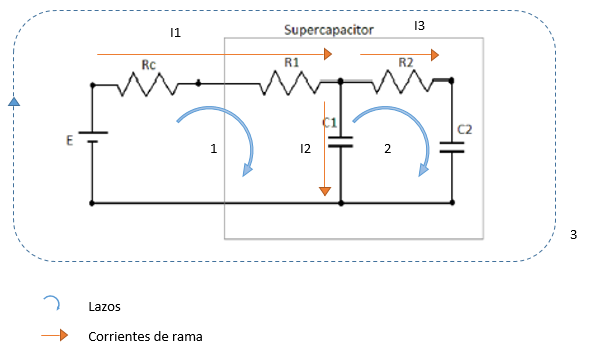

Para modelar el comportamiento de carga y descarga de un supercapacitor, trabajaremos con un circuito modelo equivalente. En este modelo, el supercapacitor es representado por dos ramas de capacitancias en paralelo, conectados a una fuente de voltaje y una resistencia en serie que controla la magnitud de la corriente de carga.

Cualquier sistema de segundo orden tiene una respuesta oscilatoria a una entrada en escalón y tiene dos tipos independientes de almacenamiento de energía (por ejemplo un circuito RLC). Su función característica puede tener 2 raíces complejas conjugadas. La función de transferencia genérica para cualquier sistema de segundo orden es la siguiente, donde 𝞽 es la constante de tiempo y 𝛇 es el coeficiente de amortiguación:

La función de transferencia del circuito equivalente del supercapacitor (llevado al dominio de Laplace) tiene la misma forma que un sistema de segundo orden general. Por lo tanto, podemos calcular el constante de tiempo y factor de amortiguación para nuestro modelo.

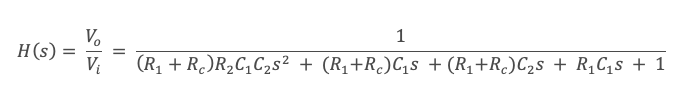

### Modelado en ecuaciones diferenciales mediante leyes de Kirchhoff.

Analizando el circuito por medio de las leyes de Kirchoff, tenemos lo siguiente. 

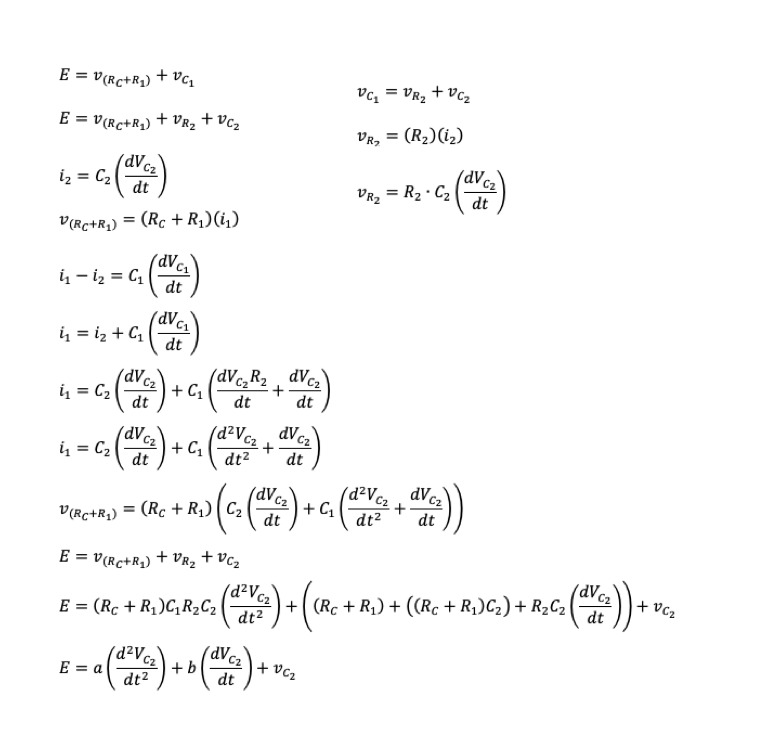

Una vez sustituidos los coeficinetes, la ecuacion diferencial tiene la forma 

.00011y'' + .131y'+y = 5

Se introdujo esta ecuacion en wolfram alpha, y la forma general de la solucion de la misma es 

y(x) = c1e^(-1183.23 x) + c2e^(-7.68316 x) + 5.

Sabemos ademas las condiciones iniciales y(0)=0 y y'(0)=0, esto nos permite conocer las constantes las cuales son  

y(x) = 5+ 0.0326792 e^(-1183.23 x) - 5.03268 e^(-7.68316 x)

Sabiendo esto, podemos modelar el cambio en el voltaje del capacitor en relacion al tiempo 

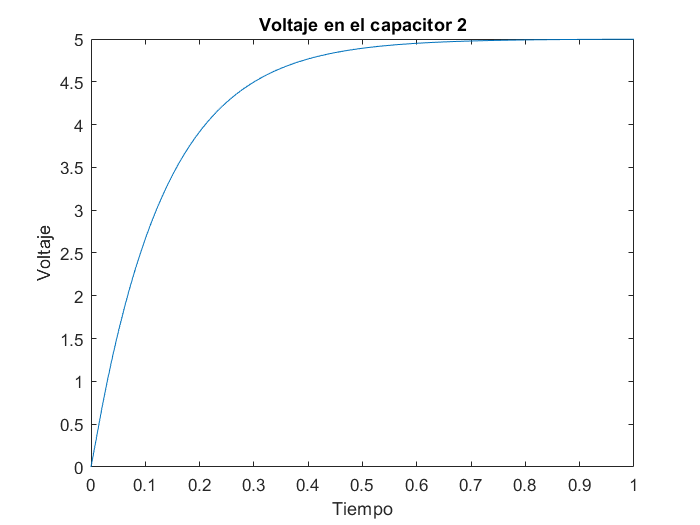

clear
R1=100; 
R2=100; 
RC=1000; 
C1=10*10^-6; 
C2=100*10^-6;

a=(R1+RC)*C1*R2*C2;
b=(R1+RC)*C1+(R1+RC)*C2+R2*C2;
c=1;
x=linspace(0,1);
y= 5+0.0326792*exp(-1183.23.*x) - 5.03268*exp(-7.68316.*x);

plot(x,y)
title("Voltaje en el capacitor 2")
xlabel("Tiempo")
ylabel("Voltaje")
ylim([0,5])

Como punto adicional, para comparar nuestros valores con el comportamiento real del circuito, usamos el paquete de analisis de señales de matlab y nuestros coeficientes para graficar el comportamiento del capacitor usando la funcion step, con la cual observamos que el comportamiento es el mismo por lo que consideramos que nuestra solucion es correcta

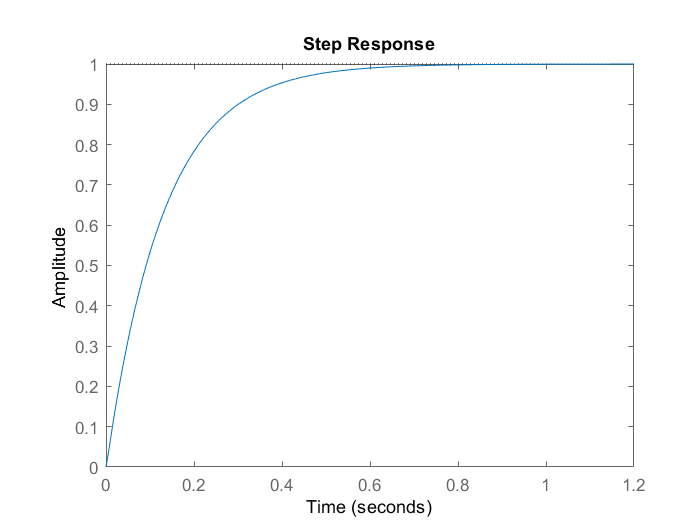

g=tf(1,[a b c]);
step(g)

### **Calculo de constantes de tiempo**

Para encontrar la constante de tiempo del capacitor que estamos buscando, se toma esta ecuaicon como el polinomio caraceristico de la ED.

.00011y'' + .131y'+y=0

Se iguala a 0, pues esto es parte del proceso de la resolucion de la ED

Se resuelve usando la formula general, y se toma la raiz con el valor absoluto mas bajo, esta sera la constante tao del supercapacitor

p=[a,b,c];
t= roots(p);
%Aqui se toma el valor maximo en lugar del minimo, pues ambos coeficientes
%son negativos, y se requiere el que tiene el valor absoluto menor
tmin=max(t);

El tiempo de carga al 99% esta dado por 5/tMinima en segundos 

tcarga=5/abs(tmin);
disp("El tiempo de carga al 99% en el segundo capacitor es"+tcarga+"segundos")

El tiempo de carga al 99% en el segundo capacitor es0.65077segundos


Este resultado coincide con el de la grafica. 

### Simulacion en LT Spice

Por su parte, la simulacion de este circuito en LT spice se ve asi 

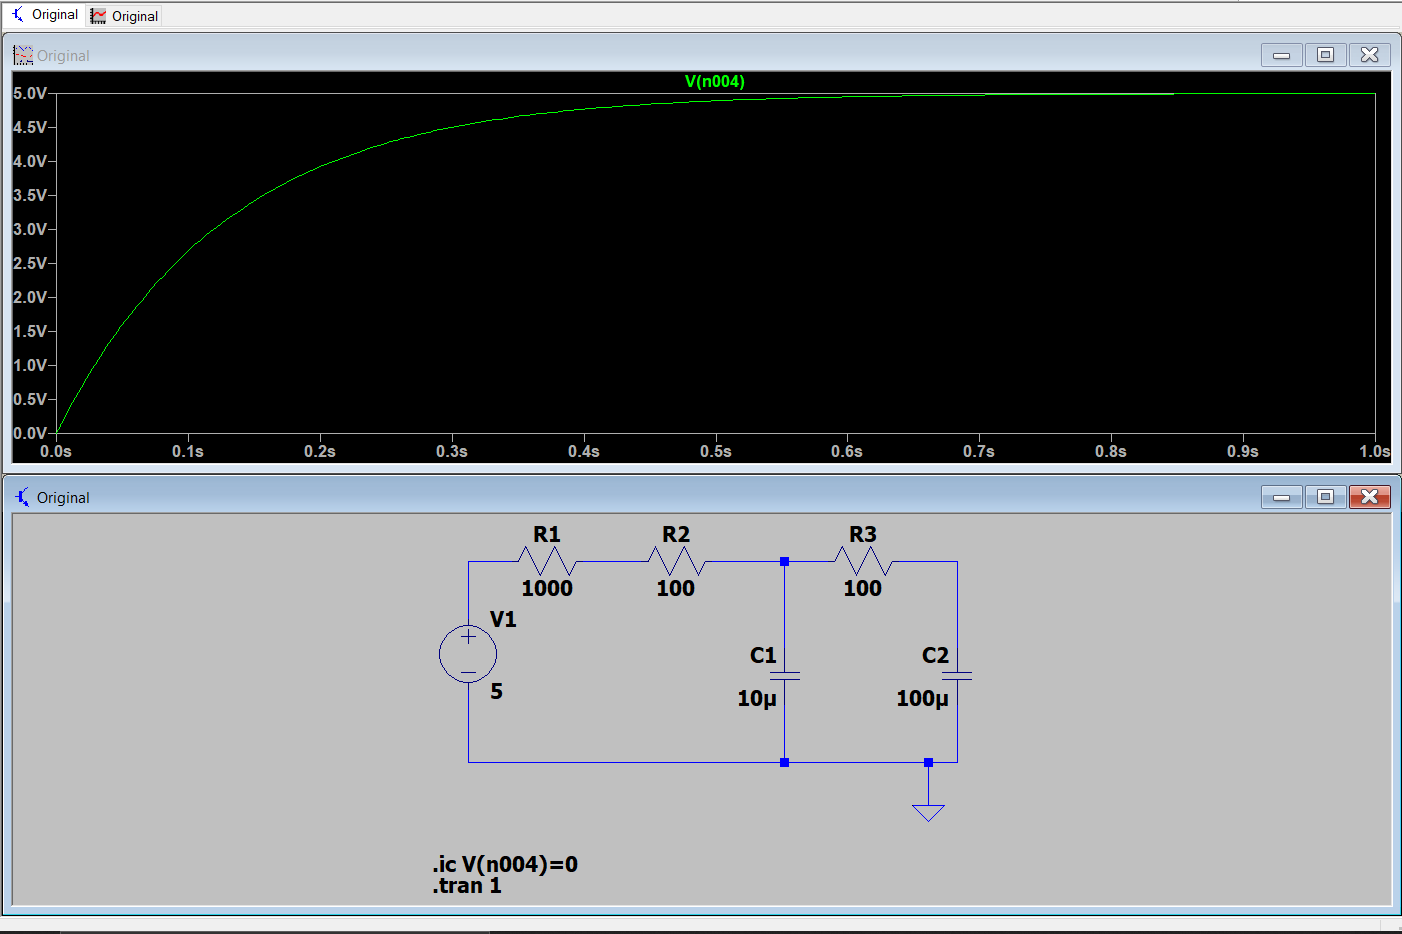

### Diseño

Se nos pide encontrar un valor para RC de manera que el tiempo de carga se reduzca a 100 ms. La manera mas facil de hacer esto es a prueba y error, Reduciendo el valor de RC en varias iteraciones hasta que la formula 5/abs(tmin) sea menor o igual a 100 ms. El siguiente while obtiene este valor por fuerza bruta modificando gradualmente RC. Sabemos que debe reducirse pues a menos resistencia mas flujo de corriente. 

RC100Ms=1000; 
%El .105 es para darle algo de tolerancia al programa, si se usaba .100 el
%valor de retorno era negativo

%Valor arbitrario para entrar al while
tcarga1000Ms=1000;
while tcarga1000Ms>0.105
a100Ms=(R1+RC100Ms)*C1*R2*C2;
b100Ms=(R1+RC100Ms)*C1+(R1+RC100Ms)*C2+R2*C2;
c100Ms=1;
p100Ms=[a100Ms,b100Ms,c100Ms];
t100Ms = roots(p100Ms);
tmin100Ms=max(t100Ms);
tcarga1000Ms=5/abs(tmin100Ms);
RC100Ms=RC100Ms-0.001;
end
disp("El valor de RC que reduce el tiempo de carga a "+tcarga1000Ms+" es "+RC100Ms)

El valor de RC que reduce el tiempo de carga a 0.105 es 4.523


Obtenemos la nueva ecuacion diferencial con los nuevos valores de a,b y c.

Nuestra nueva ecuaicion diferencial tiene la forma 

1.0452e-05y''+0.0215y'+y=5

Las condiciones iniciales siguen siendo las mismas, por lo que y(0)=0, y'(0)=0

Resolvemos esta ecuacion diferencial usando wolfram. 

**Forma general:**

y(x) = c_1 e^(-2009.41 x) + c_2 e^(-47.6137 x) + 5

**Solucion particular:**

y(x) = 0.121352 e^(-2009.41 x) - 5.12135 e^(-47.6137 x) + 5

Por ultimo graficamos el voltaje del capacitor con este nuevo valor de RC, y comparamos con la simulacion en LT spice, asi como del setp response

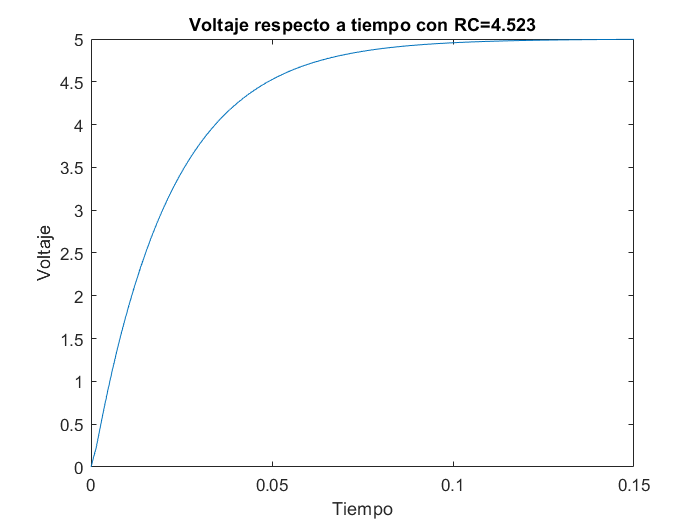

x1=linspace(0,.15);
y1=0.121352*exp(-2009.41.*x1) - 5.12135*exp(-47.6137.*x1) + 5;
plot(x1,y1)
ylim([0,5])
title("Voltaje respecto a tiempo con RC="+RC100Ms)
xlabel("Tiempo")
ylabel("Voltaje")

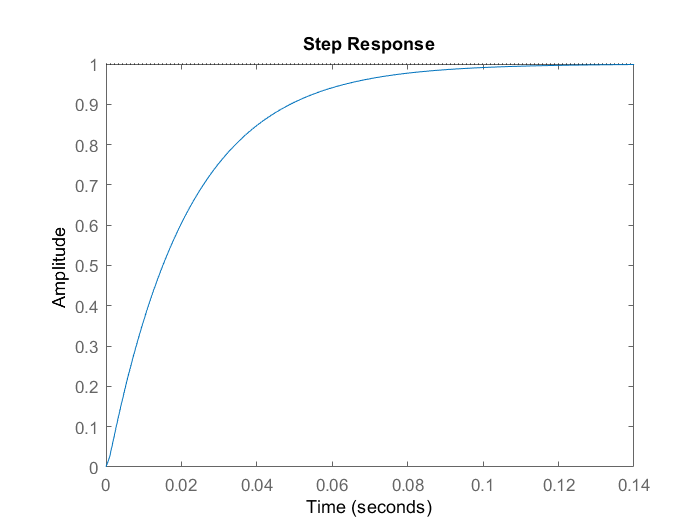

g100Ms=tf(1,[a100Ms b100Ms c100Ms]);
step(g100Ms)

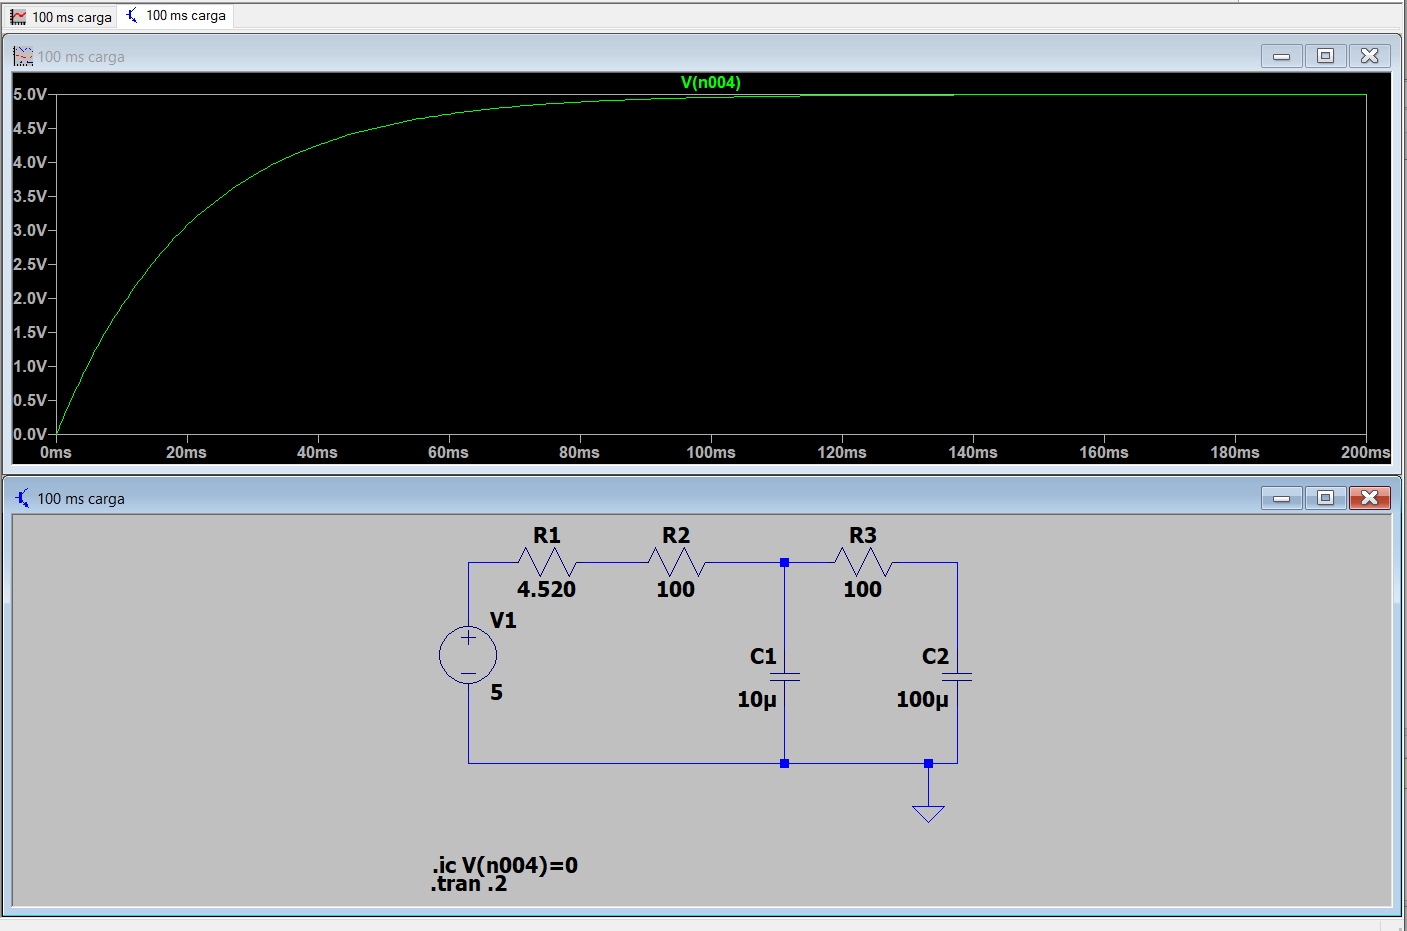

### Conclusiones individuales

Miguel: Considero trascendente el modelado que hicimos. Pese a no haber cubierto ecuaciones diferenciales en clase, fuimos capaces de representar el comportamiento de un sistema descrito por una ecuación diferencial de segundo orden. Aunque no resolvimos las ecuaciones diferenciales a mano, tengo cierto conocimiento de las mismas, y fue enriquecedor ver como estas se ponen en accion para deducir el modelado de un circuito como este desde 0, y como estas nos pueden ayudar a hacer cosas como las del punto de Diseño, donde tenemos una resistencia desconocida, esto ultimo tiene aplicaciones en el mundo real, pues nos podriamos ver en ua situacion en la que requerimos aumentar o reducir el tiempo de carga del capacitor (por poner un ejemplo). Sin duda no podriamos haber llevado a cabo este proyecto sin ayuda de las herramientas tecnologicas a nuestro alcance. Me llevo sobre todo la parte de la importancia de la modelacion. 

Michelle: Fue complicado la parte de las ecuaciones diferenciales ya que no lo vimos a profundidad en clase, al realizar la investigacion fui aprendiendo mas sobre ecuaciones diferenciales de segundo orden, sobre los circuitos RC en cascada y mas que nada el funcionamiento de un circuito con un supercapacitor, ayudo bastante la modelacion de las ecuaciones y del circuito, ver como todos los conceptos matematicos y fisicos se relacionan entre si y de esta forma comprender mas a profundidad el comportamiento del circuito y poder sacar deducciones mas concretas. Con los varios ejemplos que encontre, esto nos podria ayudar a equilibrar las cantidas de carga asi como de otros elementos como la resistencia, voltaje, capacitancia, etc., que nos ayudaran a crear un modelo equivalente a un supercapacitor de acuerdo a lo deseado o hacer solo ciertas modificaciones a alguno que se tenga. En general, comprendí la diferencia entre circuitos y su comportamiento en cada uno de ellos.

Matias: El desafio de unir todos los conocimientos aprendidos desde el inicio de la unidad de formación ha sido dificil, pero fructífero. La aplicación de la teoría vista a simulaciones y modelos nos ha permitido reconocer con mayor claridad las relaciones entre variables en dichos modelos. El uso de circuitos modelos para predecir el comportamiento de instrumentos eléctricos es una habilidad útil que seguramente nos servirá para otros proyectos a futuro.

Pedro: Desde mi punto de vista fue un excelente ejercicio para ver las aplicaciones de ecuaciones diferenciales, pues conociendo estas podemos llegar a conocer las variaciones de un valor determinado en razón del tiempo y que mejor para esto que el funcionamiento de un capacitor, pues gracias al modelado de este, se puede llegar a la conclusión de que la función de los mismo determina que dentro de un mismo circuito los elementos que influyen en este varíen como sería el caso de la corriente que no se comporta de la misma forma en ambos capacitores pues el funcionamiento de los mismos altera el entorno del otro y esto se puede entiende perfectamente en la ecuación diferencial obtenida pues se tiene como resultado dos constantes de tiempo que corresponden al funcionamiento de uno y del otro, por eso mismo considero que este ejercicio fue una muestra muy clara de las simulaciones matematicas y sus multiples aplicaciones.